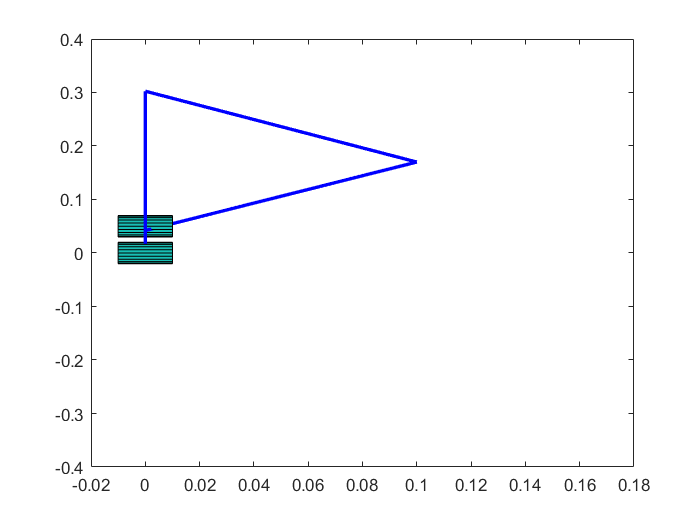

W=0;  % the x direction coordination the first joint of leg
L=0.05; 

l1 = 0.05;%change length
l2 = 0.3;
d  = 0.05;
 
for i = 1
for j = 1
    T = FK_2DOF_Leg1_SD_e(i,j);
    plot(T(2),T(3),'r');hold on;
    DrawCylinder([0;0;0], [1;0;0], 0.02,0.02, 0);hold on;
    DrawCylinder([0;0.05;0], [1;0;0], 0.02,0.02, 0);hold on;
    Connect3D([0;0;0],[0;L-d+l1*sin(i);l1*cos(i)] ,'b',2);hold on;
    Connect3D([0;0;0],[0;L+l2*sin(j);l2*cos(i)] ,'b',2);hold on;
    Connect3D([T(1);T(2);T(3)],[0;L-d+l1*sin(i);l1*cos(i)] ,'b',2);hold on;
    Connect3D([T(1);T(2);T(3)],[0;L+l2*sin(j);l2*cos(i)] ,'b',2);hold on;
end
end